# MATLAB을 활용한 AI 프로그래밍 - 충남대학교 김병관

- 한국전자파학회 2022 하계 전파교육 단기강좌 (8월 5일, 12일) 

- 문의사항: byungkwan.kim@cnu.ac.kr 

# 4. CNN의 응용: ResNet 

## [**주의] 학습 시간이 오래 걸리므로 CPU로는 학습 권장하지 않음. **

- CNN을 많이 stack 할수록 성능이 좋아졌지만, 20층 부터 성능의 개선이 크게 존재하지 않거나, 오히려 줄어듬. 

- 이러한 현상을 Degradation Problem이라고 부름. 

- Skip connection / Residual Learning 이라는 개념의 등장 (2015)

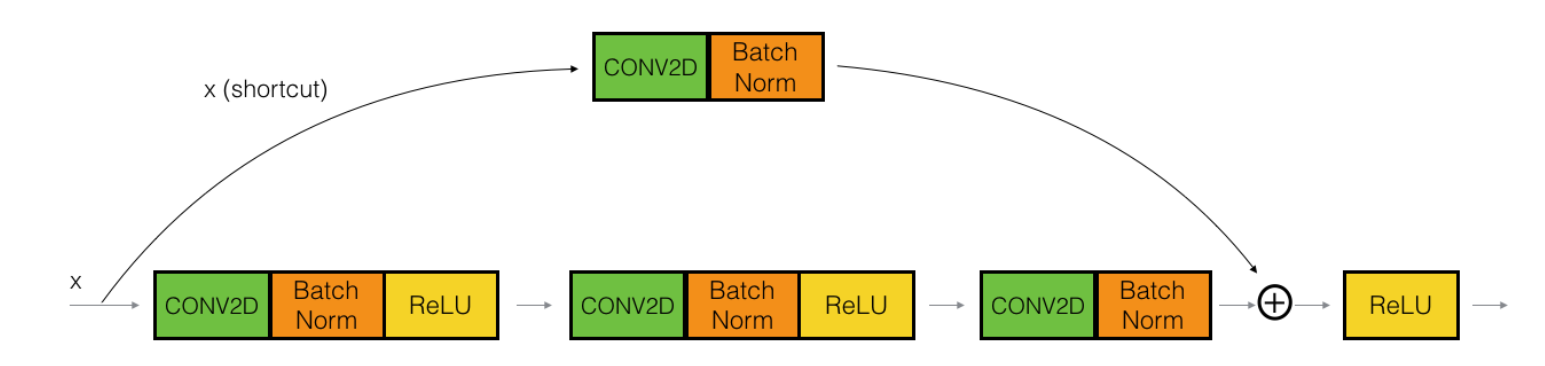

### 1) Import image data into MATLAB workspace

- 학습에 사용될 Image는 각각 폴더 내에 존재함. **(MATLAB 현재 폴더 확인)**

inputSize = [72 72 3];
numClasses = 10;
hf_radio = imageDatastore("./", "IncludeSubfolders",true,"FileExtensions",'.png','LabelSource','foldernames');
[hf_radio_train, hf_radio_val] = splitEachLabel(hf_radio,0.7,'randomized');

### 2) Configure resnet using MATLAB Machine Learning Toolbox

- **MATLAB 에서 Resnet 구성 시 현재 두가지 방법이 있음**

- **Toolbox에서 제공된 resnetLayers 를 통해 구성 (추천) **

- 직접 skip connection을 layer 별로 정의해서 추가 해 주는 경우 (https://kr.mathworks.com/help/deeplearning/ug/train-residual-network-for-image-classification.html)

`        lgraph = connectLayers(lgraph,``'reluInp'``,``'add11/in2'``);`

`        lgraph = connectLayers(lgraph,``'relu11'``,``'add12/in2'``);`

initialFilterSize = 3;
numInitialFilters = 16;
initialStride = 1;

lgraph = resnetLayers(inputSize,numClasses, ...
    InitialFilterSize=initialFilterSize, ...
    InitialNumFilters=numInitialFilters, ...
    InitialStride=initialStride, ...
    InitialPoolingLayer="none", ...
    StackDepth=[4 3 2], ... 
    NumFilters=[16 32 64]);

analyzeNetwork(lgraph)

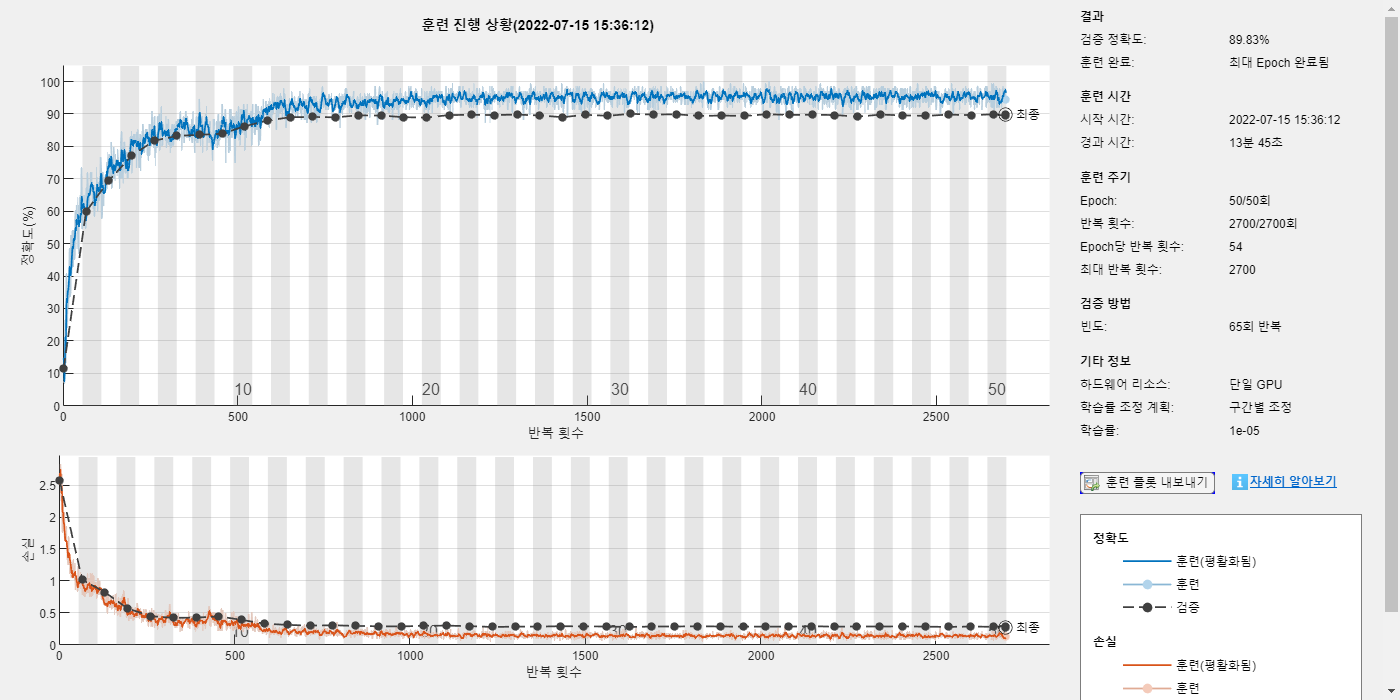

miniBatchSize = 128;
learnRate = 0.1*miniBatchSize/128;
valFrequency = 65;
options = trainingOptions('sgdm', ...
    'InitialLearnRate',learnRate, ...
    'MaxEpochs',50, ...
    'MiniBatchSize',miniBatchSize, ...
    'VerboseFrequency',valFrequency, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',hf_radio_val, ...
    'ValidationFrequency',valFrequency, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',10, ...
    'ExecutionEnvironment','gpu');

net = trainNetwork(hf_radio_train,lgraph,options);

### 4) 정확도 분석을 위한 Inference (추론) 수행 

- YPred 라는 변수에 Network 가 추론한 결과값이 저장되며,

- YValidation 및 YTrain은 학습을 위해 제공한 정답 Label이 들어 있음.

YPred = classify(net,hf_radio_val);
YValidation = hf_radio_val.Labels;
YTrain = hf_radio_train.Labels;
accuracy = mean(YPred == YValidation);
YTrainPred = classify(net,hf_radio_train);
validationError = mean(YPred ~= YValidation);
trainError = mean(YTrainPred ~= YTrain);
disp("Accuracy: " + accuracy*100 + "%");
disp("Training error: " + trainError*100 + "%");
disp("Validation error: " + validationError*100 + "%");

### 5) Class 별 정확도 분석을 위한 Confusion Matrix 결과 

Accuracy: 89.8333%


Training error: 4.1714%


Validation error: 10.1667%


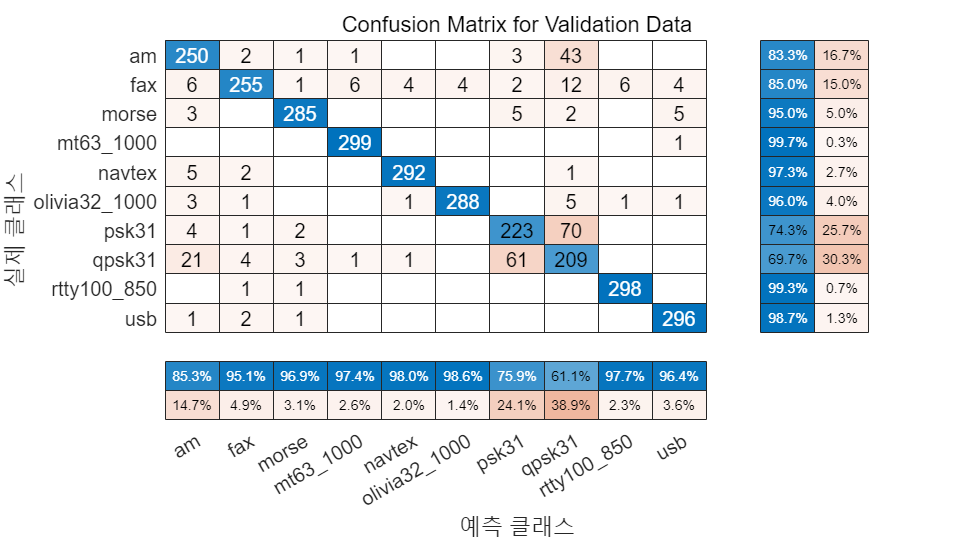

cm = confusionchart(YValidation,YPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

confusionMat = confusionmat(YValidation,YPred);
confusionMat = confusionMat';
precision = diag(confusionMat)./sum(confusionMat,2);
overall_precision = mean(precision)
recall= diag(confusionMat)./sum(confusionMat,1)';
overall_recall = mean(recall)
f1_score = 2*(overall_precision*overall_recall)/(overall_precision+overall_recall)
